# Develop differential equations for a gantry crane

clear variables

results_dir = 'results';
if ~isfolder(results_dir)
    mkdir(results_dir)
end

The equations below were developed from the cart-pole equations presented by:

- R. V. Florian, 2007, Correct equations for the dynamics of the cart-pole system.

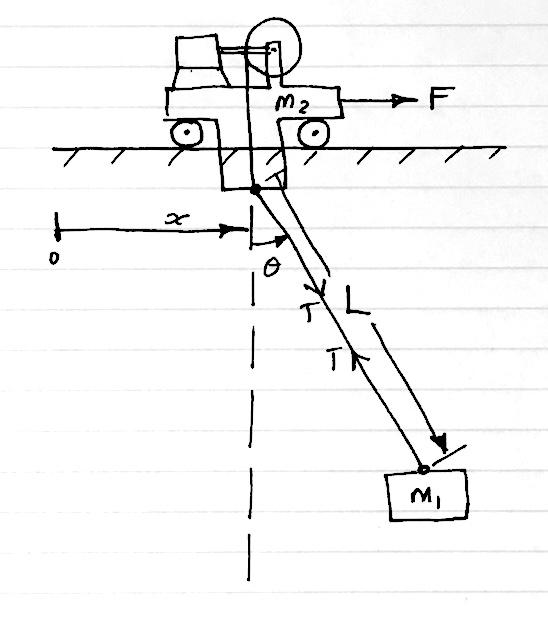

Note: $\theta \;$ is defined differently to the cart pole system.

State variables

- Horizontal position of cart (from left) $x\left(t\right)$

- Horizontal velocity of cart $\dot{x} \left(t\right)$

- Angle of cable (anti-clockwise from vertical down position) $\theta \left(t\right)$

- Angular velocity of cable $\dot{\;\theta \;} \left(t\right)$

- Cable length $L\left(t\right)$

Other variables

- Downwards force on track from cart $N_c \left(t\right)$

- Frictional force exerted on cart by track $F_F \left(t\right)$

- Force exerted on cart by cable (and on load) $T\left(t\right)$

Potential input variables

- Horizontal driving force on cart $F\left(t\right)$

- Speed of cable leaving winch $\dot{L} \left(t\right)$

Parameters

- Cart mass $m_c$

- Load mass $m_p$

- Acceleration due to gravity $g$

- Coefficient of friction for cart and track $\mu_c$

- Radius of the load, $r$

- Drag coefficient of load $c_d$

- Mass density of air $\rho_a$

System of DAEs


$$\begin{array}{l}
N_c =\left(m_c +m_p \right)g+m_p L\left(\ddot{\theta} \;\sin \theta +{\dot{\theta} }^2 \;\cos \theta \right)\\
\ddot{\theta} =\frac{g\;\sin \theta +\cos \theta \left\lbrace \frac{-F-m_p L{\dot{\theta} }^2 \left(\sin \theta -\mu_c \;\textrm{sgn}\left(N_c \dot{x} \right)\cos \theta \right)}{m_c +m_p }+\mu_c g\;\textrm{sgn}\left(N_c \dot{x} \right)\right\rbrace +\frac{{\pi^{3\;} \rho c_d L^2 r}^2 }{2m_p }\textrm{sgn}\left(\dot{\theta} \right){\dot{\theta} }^2 }{L\left\lbrace \frac{4}{3}-\frac{m_p \cos \theta }{m_c +m_p }\left(\cos \theta +\mu_c \;\textrm{sgn}\left(N_c \dot{x} \right)\right)\right\rbrace }\\
\ddot{x} =\frac{F+m_p L\left({\dot{\theta} }^2 \;\sin \theta -\ddot{\theta} \;\cos \theta \right)-\mu_c N_c \textrm{sgn}\left(N_c \dot{x} \right)}{m_c +m_p }
\end{array}$$


## First, define an autonomous system

i.e. `F(t) = 0`, `L(t) = l` (constant)

% Define symbolic variables
syms x(t) theta(t) N_c(t) F_f(t) F_d(t) F m_c m_p L g muc r c_d rho

% Coulomb friction model
F_f(t) = muc * N_c * sign(N_c * diff(x(t)));

D2xt


% Tangential (clockwise) and radial (outward) components of 
% velocity of load through air
v_t = pi * L * diff(theta(t)) + diff(x(t)) * cos(theta(t));
v_r = diff(x(t)) * sin(theta(t));

% Components of drag force on load in tangential (anti-clockwise) and 
% radial (inward) directions
F_dt = 0.5 * rho * c_d * pi * r^2  * v_t^2;
F_dr = 0.5 * rho * c_d * pi * r^2  * v_r^2;
% Downward force of cart on track
eqn1 = N_c == ...
    (m_c + m_p) * g ...
    - m_p * L * (diff(theta(t), 2) * sin(theta(t)) + diff(theta(t))^2 * cos(theta(t))) ...
    + F_dr * cos(theta(t))

$$eqn1(t) = N_{c}\left(t\right)=g\,\left(m_{c}+m_{p}\right)-L\,m_{p}\,\left(\sin\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)+\cos\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}\right)+1.5708\,c_{d}\,r^{2}\,\rho \,\cos\left(\theta \left(t\right)\right)\,{\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}$$

% eqn2 = diff(theta(t), 2) == ...
%     (g * sin(theta(t)) + cos(theta(t)) * ( ...
%         (-F - mp * l * diff(theta(t))^2 * (sin(theta(t)) + muc * sign(Nc) * sign(diff(x(t))) * cos(theta(t))) ...
%      ) / (mc + mp) + muc * g * sign(Nc) * sign(diff(x(t)))) - mup * diff(theta(t)) / (mp * l) ) ...
%     / (l * (4/3 - mp * cos(theta(t)) / (mc + mp) * (cos(theta(t)) - muc * sign(Nc) * sign(diff(x(t))))))

% Cart-track friction force - in opposite direction to cart travel
eqn2 = F_f == muc * N_c * sign(N_c * diff(x(t)))

$$eqn2(t) = F_{f}\left(t\right)=\mathrm{muc}\,\mathrm{sign}\left(N_{c}\left(t\right)\,\frac{\partial }{\partial t}x\left(t\right)\right)\,N_{c}\left(t\right)$$

% Aerodynamic drag force - in opposite direction to velocity of load
eqn3 = F_d == 0.5 * rho * c_d * pi * r^2  * (v_t^2 + v_r^2)

$$eqn3(t) = F_{d}\left(t\right)=1.5708\,c_{d}\,r^{2}\,\rho \,\left({\sin\left(\theta \left(t\right)\right)}^{2}\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}+{\left(3.1416\,L\,\frac{\partial }{\partial t}\theta \left(t\right)+\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}\right)$$

% Angular acceleration
eqn4 = diff(theta(t), 2) == ( ...
        g * sin(theta(t)) ...
        + cos(theta(t)) * ( ...
            (-F - m_p * L * diff(theta(t))^2 * sin(theta(t)) + F_f + F_dr * sin(theta(t))) ...
        ) / (m_c + m_p) ...
        - F_dt / m_p ...
    ) / (L * (4/3 - m_p * cos(theta(t))^2 / (m_c + m_p)))

$$eqn4(t) = \frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)=\frac{\frac{\cos\left(\theta \left(t\right)\right)\,\left(-1.5708\,c_{d}\,\rho \,r^{2}\,{\sin\left(\theta \left(t\right)\right)}^{3}\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}+L\,m_{p}\,\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}+F-F_{f}\left(t\right)\right)}{m_{c}+m_{p}}-g\,\sin\left(\theta \left(t\right)\right)+\frac{c_{d}\,r^{2}\,\rho \,{\left(3.1416\,L\,\frac{\partial }{\partial t}\theta \left(t\right)+\cos\left(\theta \left(t\right)\right)\,\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}\,1.5708}{m_{p}}}{L\,\left(\frac{m_{p}\,{\cos\left(\theta \left(t\right)\right)}^{2}}{m_{c}+m_{p}}-1.3333\right)}$$

% Cart horizontal acceleration
eqn5 = diff(x(t), 2) == ( ...
        F ...
        + m_p * L * (diff(theta(t))^2 * sin(theta(t)) - diff(theta(t), 2) * cos(theta(t))) ...
        - F_f ...
        - F_dr * sin(theta(t)) ...
    ) / (m_c + m_p)

$$eqn5(t) = \frac{\partial^{2}}{\partial t^{2}}x\left(t\right)=\frac{F-F_{f}\left(t\right)+L\,m_{p}\,\left(\sin\left(\theta \left(t\right)\right)\,{\left(\frac{\partial }{\partial t}\theta \left(t\right)\right)}^{2}-\cos\left(\theta \left(t\right)\right)\,\frac{\partial^{2}}{\partial t^{2}}\theta \left(t\right)\right)-1.5708\,c_{d}\,r^{2}\,\rho \,{\sin\left(\theta \left(t\right)\right)}^{3}\,{\left(\frac{\partial }{\partial t}x\left(t\right)\right)}^{2}}{m_{c}+m_{p}}$$

eqns = [eqn1 eqn2 eqn3 eqn4 eqn5];
vars = [x(t); theta(t); N_c(t); F_f(t); F_d(t)];
origVars = length(vars);

Check Incidence of Variables

M = incidenceMatrix(eqns, vars)

M =      1     1     1     0     0
     1     0     1     1     0
     1     1     0     0     1
     1     1     0     1     0
     1     1     0     1     0


Reduce Differential Order

[eqns, vars] = reduceDifferentialOrder(eqns, vars)

$$vars = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ N_{c}\left(t\right)\\ F_{f}\left(t\right)\\ F_{d}\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right) \end{array}\right)$$

Check Differential Index of System

if ~isLowIndexDAE(eqns, vars)
    disp("Reducing Differential Index...")
    % Reduce Differential Index with reduceDAEIndex
    [DAEs, DAEvars] = reduceDAEIndex(eqns, vars)
    % Eliminate redundant equations and variables
    [DAEs, DAEvars] = reduceRedundancies(DAEs, DAEvars)
    % Check the differential index of the new system
    assert(isLowIndexDAE(DAEs, DAEvars))
else
    DAEs = eqns;
    DAEvars = vars;
end

### Convert DAE system to MATLAB function

pDAEs = symvar(DAEs);
pDAEvars = symvar(DAEvars);
extraParams = setdiff(pDAEs, pDAEvars)

$$extraParams = \left(\begin{array}{ccccccccc} F & L & c_{d} & g & m_{c} & m_{p} & \mathrm{muc} & r & \rho \end{array}\right)$$

Create the function handle. 

%f = daeFunction(DAEs, DAEvars, F, L, c_d, g, m_c, m_p, muc, r, rho);

To save the DAE equations as a function script use this option

filename = 'craneDAEFunction.m';
f = daeFunction(DAEs, DAEvars, F, L, c_d, g, m_c, m_p, muc, r, rho, 'File', filename);

### Set parameter values

Define parameter values as struct

params = struct();
params.F = 10;
params.L = 5;
params.c_d = 0.47;  % drag coefficient of a sphere = 0.47
params.g = 9.8;
params.m_c = 5;
params.m_p = 2;
params.muc = 0.2;
params.r = 1;  % radius of load
params.rho = 1.293;  % density of air (kg/m3)

### Checks of function calculations

% With no external force (F=0)
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, params.L, params.c_d, params.g, params.m_c, params.m_p, params.muc, params.r, params.rho);

% Equilibrium point 1: stationary at vertical down position
y0 = [0; 0; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0 = [0; 0; 0; 0; 0; 0; 0];
assert(all(F_DAE(0, y0, yp0) == 0))
% Check at any x position
y0 = [2; 0; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0 = [0; 0; 0; 0; 0; 0; 0];
assert(all(F_DAE(0, y0, yp0) == 0))
y0 = [-3; 0; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0 = [0; 0; 0; 0; 0; 0; 0];
assert(all(F_DAE(0, y0, yp0) == 0))

% Equilibrium point 2: stationary at vertical up position
y0 = [0; pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0 = [0; 0; 0; 0; 0; 0; 0];
assert(all(abs(F_DAE(0, y0, yp0)) < 1e-15))
% Check at any x position
y0 = [10; pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0 = [0; 0; 0; 0; 0; 0; 0];
assert(all(abs(F_DAE(0, y0, yp0)) < 1e-15))

% Accelerates towards stable equilibrium
y0est = [0; 0.99*pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
opt = odeset('RelTol', 10.0^(-9), 'AbsTol', 10.0^(-9));
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1          y0        yp0   
    ____________    ______    ________

    "x(t)"               0           0
    "theta(t)"      3.1102           0
    "N_c(t)"        68.582           0
    "F_f(t)"             0           0
    "F_d(t)"             0           0
    "Dxt(t)"             0    0.083888
    "Dthetat(t)"         0    0.058751



assert(all(yp0(1:5) == 0))
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(yp0(6) > 0 && yp0(7) > 0)

% Accelerates towards stable equilibrium
y0est = [0; 1.01*pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1          y0         yp0   
    ____________    ______    _________

    "x(t)"               0            0
    "theta(t)"       3.173            0
    "N_c(t)"        68.582            0
    "F_f(t)"             0            0
    "F_d(t)"             0            0
    "Dxt(t)"             0    -0.083888
    "Dthetat(t)"         0    -0.058751



assert(all(yp0(1:5) == 0))
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(yp0(6) < 0 && yp0(7) < 0)

% Accelerates away from unstable equilibrium
y0est = [0; 0.01*pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1           y0          yp0   
    ____________    ________    _________

    "x(t)"                 0            0
    "theta(t)"      0.031416            0
    "N_c(t)"          68.582            0
    "F_f(t)"               0            0
    "F_d(t)"               0            0
    "Dxt(t)"               0    -0.083888
    "Dthetat(t)"           0     0.058751



assert(all(yp0(1:5) == 0))
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(yp0(6) < 0 && yp0(7) > 0)

% Accelerates away from unstable equilibrium
y0est = [0; -0.01*pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1           y0           yp0   
    ____________    _________    _________

    "x(t)"                  0            0
    "theta(t)"      -0.031416            0
    "N_c(t)"           68.582            0
    "F_f(t)"                0            0
    "F_d(t)"                0            0
    "Dxt(t)"                0     0.083888
    "Dthetat(t)"            0    -0.058751



assert(all(yp0(1:5) == 0))
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(yp0(6) > 0 && yp0(7) < 0)

% With +ve external forcing
F_DAE = @(t, Y, YP) f(t, Y, YP, 10, params.L, params.c_d, params.g, params.m_c, params.m_p, params.muc, params.r, params.rho);
% Accelerates away from unstable equilibrium
y0est = [0; 0; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))

        Var1         y0       yp0   
    ____________    ____    ________

    "x(t)"             0           0
    "theta(t)"         0           0
    "N_c(t)"        68.6           0
    "F_f(t)"           0           0
    "F_d(t)"           0           0
    "Dxt(t)"           0      1.8182
    "Dthetat(t)"       0    -0.27273



assert(all(yp0(1:5) == 0))
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(yp0(6) > 0 && yp0(7) < 0)

% With -ve external forcing
F_DAE = @(t, Y, YP) f(t, Y, YP, -10, params.L, params.c_d, params.g, params.m_c, params.m_p, params.muc, params.r, params.rho);
% Stable equilibrium
y0est = [0; pi; (params.m_c + params.m_p)*params.g; 0; 0; 0; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);

Error using decic>sls (line 168)
Try freeing 1 fixed components.

Error in decic (line 77)
    [dy,dyp] = sls(res,dfdy,dfdyp,neq,free_y,free_yp);

disp(table(string(DAEvars), y0, yp0))
assert(all(yp0(1:5) == 0))
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(yp0(6) < 0 && yp0(7) < 0)

% Check cart-track friction force and drag force
% With no cart-track friction or drag
%F_DAE = @(t, Y, YP) f(t, Y, YP, F, L, c_d, g, m_c, m_p, muc, r, rho);
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, params.L, 0, params.g, params.m_c, params.m_p, 0, params.r, params.rho);
% In vertical down position with horizontal velocity
y0est = [0; pi; (params.m_c + params.m_p)*params.g; 0; 0; 5; 0];
yp0est = [1; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(all(abs(yp0(6:7)) < 1e-15))
% With drag but no cart-track friction
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, params.L, params.c_d, params.g, params.m_c, params.m_p, 0, params.r, params.rho);
% In vertical down position with horizontal velocity
y0est = [0; pi; (params.m_c + params.m_p)*params.g; 0; 0; 5; 0];
yp0est = [5; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
disp(table(string(DAEvars), y0, yp0))
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(abs(yp0(6)) < 1e-15 && yp0(7) < -1e-15)
% With drag but no cart-track friction
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, params.L, 0, params.g, params.m_c, params.m_p, 0, params.r, params.rho);
% In horizontal right position with horizontal velocity
y0est = [0; pi/2; (params.m_c + params.m_p)*params.g; 0; 0; 5; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(abs(yp0(6)) < 1e-15 && abs(yp0(5)) < 1e-15)
% With drag force but no cart-track friction
F_DAE = @(t, Y, YP) f(t, Y, YP, 0, params.L, params.c_d, params.g, params.m_c, params.m_p, 0, params.r, params.rho);
y0est = [0; pi; (params.m_c + params.m_p)*params.g; 0; 0; 5; 0];
yp0est = [0; 0; 0; 0; 0; 0; 0];
FIXED_Y0 = [1 1 0 0 0 1 1]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, [], opt);
% yp0(6) = D2xt(t), yp0(6) = D2thetat(t)
assert(abs(yp0(6)) < 1e-15 && yp0(7) < -1e-13)

### Find initial condition

Create function for ode15i

F_DAE = @(t, Y, YP) f(t, Y, YP, params.F, params.L, params.c_d, params.g, params.m_c, params.m_p, params.muc, params.r, params.rho);
DAEvars

$$DAEvars = \left(\begin{array}{c} x\left(t\right)\\ \theta \left(t\right)\\ N_{c}\left(t\right)\\ F_{f}\left(t\right)\\ F_{d}\left(t\right)\\ \mathrm{Dxt}\left(t\right)\\ \mathrm{Dthetat}\left(t\right) \end{array}\right)$$

Note that `Dxt(t)`, `Dthetat(t)`, ... etc. are the first derivatives of `x(t)`, `theta(t)`.

Provide an estimate of the initial condition

% Variables
% 1 degrees = 0.0172
y0est = [-3; deg2rad(180 - 0); 0; 0; 0; 0; 0];
% Their derivatives
yp0est = [0; 0; 0; 0; 0; 0; 0];

Set tolerances and do numerical search.

opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-7));
FIXED_Y0 = [1 1 0 0 0 1 1]';
FIXED_YP0 = [0 0 0 0 0 0 0]';
[y0, yp0] = decic(F_DAE, 0, y0est, FIXED_Y0, yp0est, FIXED_YP0, opt)

y0 =    -3.0000
    3.1416
   68.6000
         0
         0
         0
         0


yp0 =          0
         0
         0
         0
         0
    1.8182
    0.2727


Draw initial position

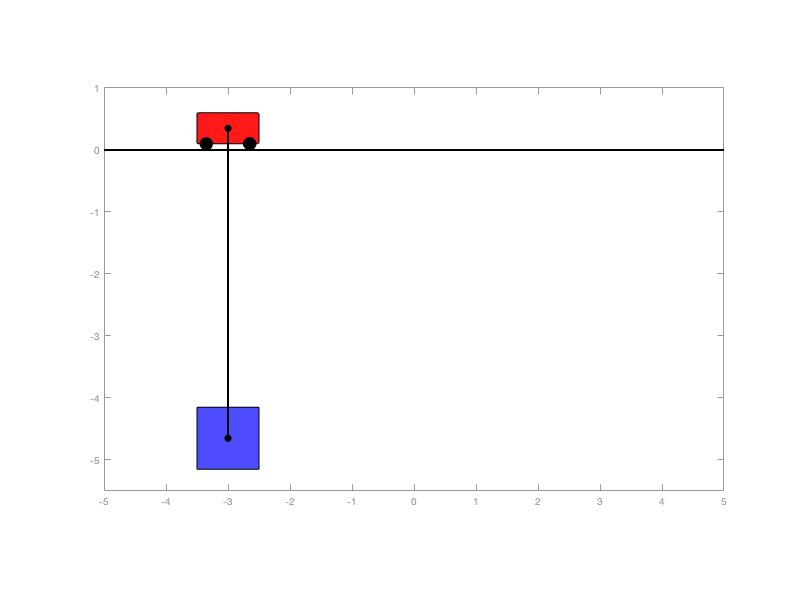

figure(1); clf
draw_crane(y0([1 3 2 4]),params)

### Solve DAEs Using ode15i

opt = odeset('RelTol', 10.0^(-7), 'AbsTol', 10.0^(-5));
[tSol, ySol] = ode15i(F_DAE, [0 2], y0, yp0, opt);

Plot solution

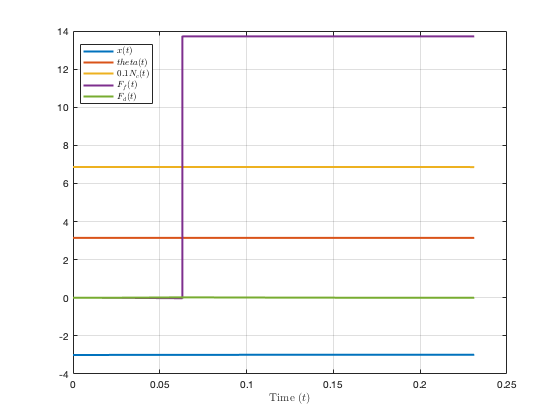

figure(2); clf
labels = arrayfun(@(i) char(DAEvars(i)), 1:origVars, 'UniformOutput', false);
y_scaling = [1 1 10 1 1];
labels{3} = strcat('0.1', labels{3});
plot(tSol, ySol(:, 1:origVars) ./ y_scaling, 'LineWidth', 2)
xlabel("Time ($t$)", 'Interpreter', 'latex')
legend(string2latex(labels), 'Location', 'best', 'Interpreter', 'latex')
grid on

### Save results to file

labels = arrayfun(@(i) char(DAEvars(i)), 1:numel(DAEvars), 'UniformOutput', false);
sim_results = array2table([tSol ySol], 'VariableNames', [{'t'} labels]);
filename = "crane_benchmark_sim.csv";
writetable(sim_results, fullfile(results_dir, filename))

### Solve using function script file

Solve the equations using the function script created by `daeFunction` above and check results are identical.

% Solve DAEs
F_DAE2 = @(t, Y, YP) craneDAEFunction(t, Y, YP, params.F, params.L, params.c_d, params.g, ...
    params.m_c, params.m_p, params.muc, params.r, params.rho);
[tSol2, ySol2] = ode15i(F_DAE2, [0 2], y0, yp0, opt);
assert(isequal(tSol, tSol2))
assert(max(ySol - ySol2, [], [1 2]) < 1e-14)

Solve using the edited function in crane_DAEs.m

% Solve DAEs
F_DAE2 = @(t, Y, YP) crane_DAEs(t, Y, YP, params);
[tSol2, ySol2] = ode15i(F_DAE2, [0 2], y0, yp0, opt);
assert(isequal(tSol, tSol2))
assert(max(ySol - ySol2, [], [1 2]) < 1e-14)